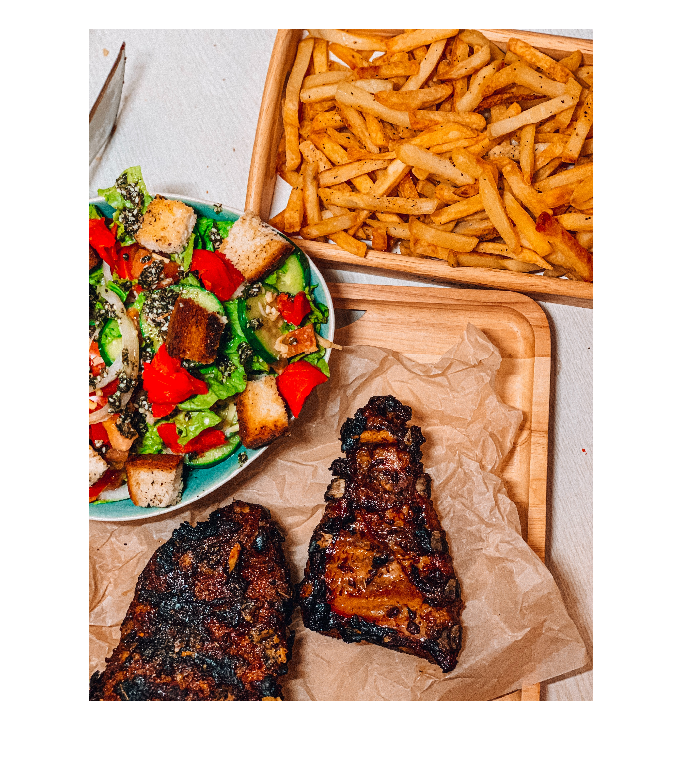

%%This matlab script will be used for experimenting with food
%%classification functions

%%Reads the image
image = imread('images/problematic/MeatDish.jpg');

%%Defines the different binary masks for the images based on color
green = Green(image);        
lightGreen = LightGreen(image);
red = MoreRed(image);
yellow = Yellow(image);
purple = Purple(image);
orange = Orange(image);

%%Fuses both green masks to cover as much green as possible
greenResult = imfuse(lightGreen,green,'blend');

%%Fuses all of the masks together with diff 
result = imfuse(greenResult, red,'diff');
result = imfuse(yellow,result,'diff');
result = imfuse(purple,result,'diff');
result = imfuse(orange, result,'diff');

%%Defines a morphological structuring object
rough = strel('disk',3);

%%Perform morphological opening on the image
roughProcessed = imopen(result,rough);
fused = imfuse(image,roughProcessed,'blend');

%%Display the images
imshow(image)

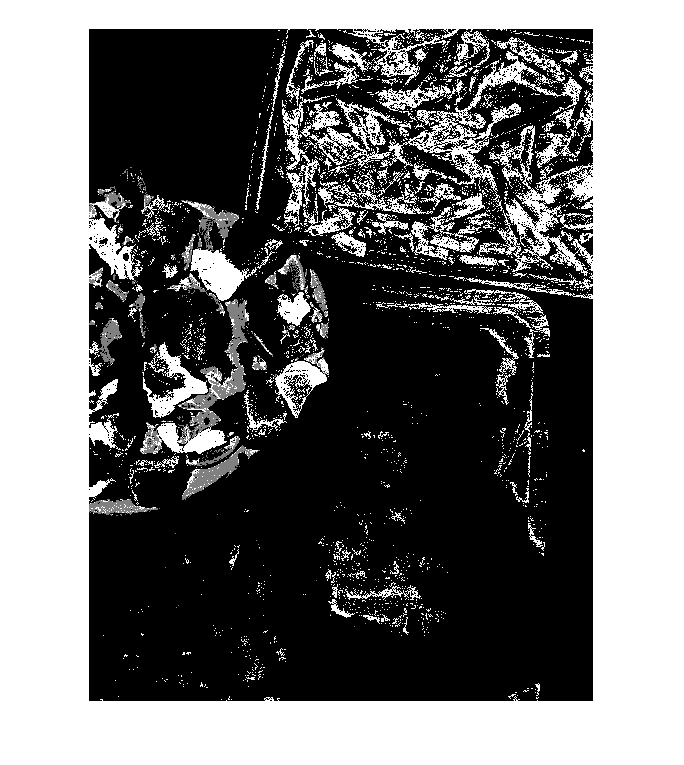

imshow(result)

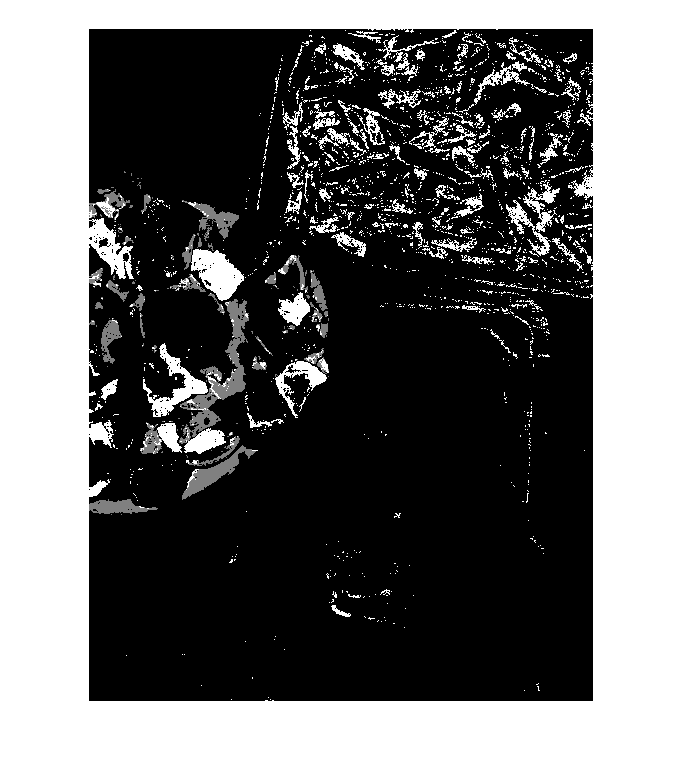

imshow(roughProcessed)

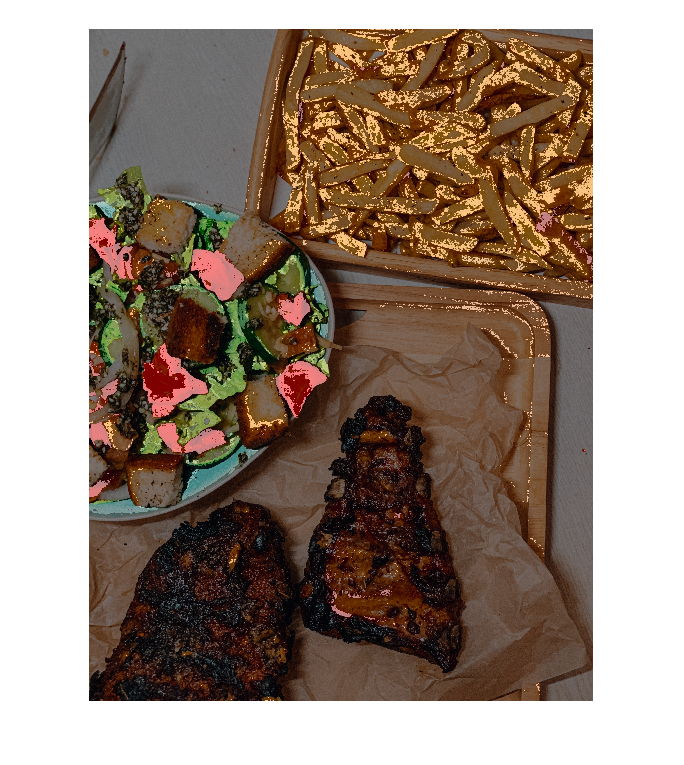

imshow(fused)